# Substitution

[⇦ Overview](matlab: OpenOverview)

A thorough understanding of the integral as an antiderivative can only take you so far. Just as with derivatives, there are integration rules that can be built through the combination of functions as well. The method of substitution that will be discussed in this live script applies to nearly every integral you will ever calculate. In fact, you will likely forget that you are even applying it in some cases because it will become so natural to use!

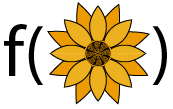

The method of substitution allows you to replace a complicated integral with a simpler one.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

clear
 

## Inverting the Chain Rule for Derivatives

Remember that the chain rule for derivatives looks like 


$$\frac{d}{dx}\left[(f\circ g)(x)\right]=\frac{df}{dg}\cdot \frac{dg}{dx}=f'(g)\cdot g'(x) = f'(g(x))\cdot g'(x)$$


### Substitution for Indefinite Integrals

If we apply the concept of antiderivatives to this rule, we see that 


$$f(g(x)) + C = \int \frac{d}{dx}\left[(f\circ g)(x)\right] \; dx =\int f'(g)\cdot g'(x) \; dx$$
     
$$(\Delta)$$


In fact, because $dx$ tracks the measure of a small step in the direction of integration while $g'(x)\; dx$ does the same, we can define a new measure $dg = g'(x)\; dx$ which allows us to note that


$$f(g(x))+C = \int f'(g)\; dg.$$


### Substitution for Definite Integrals

Applying the fundamental theorem of calculus, we have: 


$$\int_{g(a)}^{g(b)} f'(g) dg = \int_a^b f'(g(x)) \cdot g'(x)\; dx$$


which is 


$$f(g(b))-f(g(a)) = \int_{g(a)}^{g(b)} f'(g) dg = \int_a^b f'(g(x)) \cdot g'(x)\; dx.$$
     
$$(\star)$$


### **Practice using substitution**

Rewrite each of the following integrals in terms of the new variable provided by the substitution function. Then solve the integral.

#### **Exercise 1**

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

First, find the derivative of $g(x)$ with respect to $x$:

gprime = @(x) x;

What is the new measure going to be in terms of $g$?

NewMeasure = "dx";

If we define $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\cdot \text{New Measure}$, what is $f(g)$?

fa = @(g) g;

Calculate the function $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$.

answer = @(x,C) x;
check1a(gprime,fa,NewMeasure,answer);
 

  **Note: **In many textbooks it is common to use a variable $u$ in place of the variable $g$ in equations $(\Delta)$ and $(\star)$, or even to call this method $u$-substitution. 

#### **Exercise 2**

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$ 

Calculate the derivative $u'(t)$.

uprime = @(t) t;

Calculate the new bounds and new measure for the integral in terms of $u$. 

ua = 1;
gb = 3;
NewMeasure = "dt";

If we define $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot \text{New Measure}$, what is $f(u)$?

f = @(u)u;

Calculate the function $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$.

answer =  0;
check1b(uprime,f,ua,gb,NewMeasure,answer);
 

#### **Exercise 3**

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

Remember that $e^x$ is written as `exp(x)` in MATLAB.

gprime = @(r) r;
NewMeasure = "dr";

If we define $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \text{New Measure}$,

fc = @(q) q;
answer = @(r,C) r;
check1c(gprime,fc,NewMeasure,answer);
 

#### **Exercise 4**

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

gprime = @(w) w;
ga = -1;
gb = 2;
measure = "dw";

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot \text{New Measure},$

fb = @(g) g;

This result is still not immediately computable, so let's make another substitution with $u(g) = \ln(g)$. Remember that $\ln(g)$ is written `log(g)` in MATLAB.

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot \text{Next New Measure},$

ua = -1;
ub = 2;
nextMeasure = "dw";
fu = @(u) u;

Putting everything together, compute the result:

answer =  0;
check1d(gprime,fb,ga,gb,measure,nextMeasure,ua,ub,fu,answer);
 

## Visualizing changing variables

clear x
syms x

It can be counterintuitive to visualize how a change of variables affects your function or the resulting integral. Use this to investigate different combinations of functions. 

### One step at a time

Set up the functions to use:

f = @(x)sin(x);
g = @(x)log(x+5.001);

Choose a left endpoint $a$ and a right endpoint $b$ such that $a \leq x \leq b$:

a =-3.4; b = 2.1;
if a > b
    warning("This code assumes a<b. Please set your values accordingly.")
end
tVals = linspace(min(a,b),max(a,b),10000);
gVals = double(g(tVals));
fVals = double(f(gVals));

Visualize the graph as $f(g(x))$ vs $x$ or $f(g(x))$ vs $g(x)$:

xOrg = "indX";
if xOrg == "indX"
    displayXvsF = 1;
else
    displayXvsF = 0;
end
clear p2
fig1 = figure;
p1 = plot(gVals,fVals);
ax = p1.Parent;
ylabel(ax,"$f(g(x))$","Interpreter","latex")

if displayXvsF
    p1.XData = tVals;
    ax.XLim = [tVals(1) tVals(end)];
    title(ax,"Plotting $f(x)$ against $x$","Interpreter","latex")
    xlabel(ax,"$x$","Interpreter","latex")
else
    p1.XData = gVals;
    ax.XLim = [min(gVals) max(gVals)];
    title(ax,"Plotting $f(x)$ against $g(x)$","Interpreter","latex")
    xlabel(ax,"$g(x)$","Interpreter","latex")
end
 

  **Try**.

- $f(x) = \sin(x)$ and $g(x) = \ln(x+0.001)$ with $a=0$ and $b = 2.1$?

- $f(x) = \sin(x)$ and $g(x) = \ln(x+0.001)$ with $a=1$ and $b = 1.1$? or with $a=0$ and $b = 0.1$?  

- $f(x) = \cos(x)$ and $g(x) = e^x$ with $a = 0$ and $b=0.1$? or $a=2$ and $b = 2.1$? or $a = 2$ and $b=5$?

- $f(x) = \cos(x)$ and $g(x) = e^x$ with $a = 5$ and $b = 5$?

- Any other functions you like!

Choose a step size and an initial point:

step = 0.75; x0 = 1.1;
 
flag = "xdx";
y0 = double(f(g(x0)));
g0 = double(g(x0));
g1 = g0+step;
g2 = double(g(x0+step));
yM = max(fVals);
ym = min(fVals);

switch flag
    case "gdx"
        disp("The step size shown is dg = "+step+" and the initial point is g_0="+g0+".")
        if (g0+step > max(gVals)) || (g0+step < min(gVals))
            warning("This step size moves outside the domain window shown.")
        end
        title(ax,"Showing the effect of the chosen step size $dg =$"+step,"Interpreter","latex")
        p1.XData = gVals;
        ax.XLim = [min(gVals) max(gVals)];
        xlabel(ax,"$g(x)$","Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [g0 g0];
            p2(2).XData = [g1 g1];
        else
            hold on
            yM = max(fVals);
            ym = min(fVals);
            p2 = plot(ax,[g0 g0],[ym yM],[g1 g1],[ym yM]);
            hold off
        end
    case "xdx"
        disp("The step size shown is dx = "+step+" and the initial point is x_0="+x0+".") %#ok<*UNRCH>
        if (x0+step > max(tVals)) || (x0+step < min(tVals))
            warning("This step size moves outside the domain window shown.")
        end
        p1.XData = tVals;
        ax.XLim = [tVals(1) tVals(end)];
        t0 = x0;
        t1 = x0+step;
        y1 = double(f(g(x0+step)));
        xlabel(ax,"$x$","Interpreter","latex")
        title(ax,"Showing the effect of a constant step size $dx = $"+step,"Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [t0 t0];
            p2(2).XData = [t1 t1];
        else
            hold on
            p2 = plot(ax,[t0 t0],[ym yM],[t1 t1],[ym yM]);
            hold off
        end
    case "gdg"
        disp("The step size is dx ="+step+".")
        disp("Therefore, the step size shown is dg = "+(g2-g0)+" and the initial point is g_0="+g0+".")
        if ~isreal(g2)
            warning("This value is outside the real domain of g. Please choose a different step size.")
        else
            if (g2 > max(gVals)) || (g2 < min(gVals))
                warning("This step size moves outside the domain window shown.")
            end
            title(ax,"Showing the effect of the substitution on the step size $dg = g(x_0+dx)-g(x_0)$","Interpreter","latex")
            p1.XData = gVals;
            ax.XLim = [min(gVals) max(gVals)];
            xlabel(ax,"$g(x)$","Interpreter","latex")
            if exist("p2","var")
                p2(1).XData = [g0 g0];
                p2(2).XData = [g2 g2];
            else
                hold on
                p2 = plot(ax,[g0 g0],[ym yM],[g2 g2],[ym yM]);
                hold off
            end
        end
end

Observe the fact that the actual distance covered by a given "step size" can change quite a lot based on the choice of the initial point $x_0$ as well as the choice to consider a fixed $dg$, or a fixed $dx$ or a computed $dg = g(x_0+dx)-g(x_0)$. 

  **Try**.

- Move the values on the $x_0$ slider all the way to the right with $dx = -0.05$ and $f(x) = \sin(x)$ and $g(x) = \ln(x+5.001)$ and $b=5$. What happens? 

-  Move the values on the $x_0$ slider all the way to the left with $dx = 0.05$ and $f(x) = \sin(x)$ and $g(x) = \ln(x+5.001)$ and $a=-5$. What happens?

- Move the values on the $dx$ slider all the way to the left and to the right with a constant value of $x_0$. What happens?

- Change the dropdown to view a plot of $f(x)$ versus $g(x)$ and repeat steps 1-4. What happens?

- Try changing the functions $f(x)$ and $g(x)$, for instance to `cos(x)` and `exp(x).` If the bounds on your sliders do not make sense for the new functions, you can either set values directly by editing the numerical field or you can right click on the sliders and set new minimum and maximum values.

### Visualize the Subdivisions Over Entire Areas

Set up the functions and the bounds to use. 

clear f g p3
syms x
f(x) = sin(x); % sin(x) 
g(x) = 1/(1+x^2); % 1/(1+x^2) work well, used to use x^4
 
a =-1.2; b = 6.9;
numIntervals = 59;
tVals = linspace(min(a,b),max(a,b),ceil(1000/numIntervals)*numIntervals);
stepsize = ceil(1000/numIntervals);
gVals = double(g(tVals));
fVals = double(f(gVals));
p3 = plot(gVals,fVals);
ax3 = p3.Parent;
title(ax3,"Show the signed area between $f(g(x))$ and the $g(x)$-axis","Interpreter","latex")
hold on
xlabel(ax3,"g(x)")
ylabel(ax3,"f(g(x))")
showPosNegArea(ax3,fVals,gVals,0,2,0);

#### Animate Visualization by Original or Substitution-size Steps

First, show the positions of intervals defined by a constant step size $dg$, then subdivide the same region by intervals defined by a constant step size $dx$ under the map $g(x_k+dx) = g(a+kdx)$ where $x_k$ is the initial point of the $k^{\text{th}}$ interval. Equivalently, $x = a$ is the lower bound of the corresponding interval.  

numIntervals =59;
tVals = linspace(min(a,b),max(a,b),ceil(1000/numIntervals)*numIntervals);
stepsize = ceil(1000/numIntervals);
gVals = double(g(tVals));
fVals = double(f(gVals));
idx = 1:stepsize:length(tVals);
constdgDomain = linspace(gVals(1),gVals(end),length(idx));
constfVals = double(f(constdgDomain));
runAnimateStripes = true;     
if runAnimateStripes
    delete(ax3.Children(1:end-2))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("With constant $dg$","Interpreter","latex")
    dgGrp = animateStripes(ax3,constdgDomain,constfVals,1:length(idx),dgGrp,1);
    dgGrp = addStartEnd(ax3,constdgDomain,dgGrp);
    dgGrp.Visible = "off";
    subtitle("With constant $dx$","Interpreter","latex")
    dxGrp = animateStripes(ax3,gVals,fVals,idx,dxGrp,1);
    dxGrp = addStartEnd(ax3,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    dgGrp = animateStripes(ax3,constdgDomain,constfVals,1:length(idx),dgGrp,0);
    dgGrp.Visible = "off";
    subtitle("Showing constant $dx$","Interpreter","latex")
    dxGrp = animateStripes(ax3,gVals,fVals,idx,dxGrp,0);
    hold off
end
setXTicks(ax3,[gVals(1) gVals(end)],["g(a)" "g(b)"])

#### Show Only One Set of Steps

If the checkbox is selected, then the plot shows the region subdivided into constant-size intervals $dg$. If the checkbox is not selected, then the plot shows the region subdivided into constant-size intervals $dx$. In the latter case, the plotted interval ends occur after lengths $dg = g'(x)dx$. Because this depends on the value of $g'(x)$ it can be a linear transformation, but it can also be highly nonlinear. 

  **Try**.

- What happens when $g(x)$ is a linear function?

- What happens when $g'(x)$ is periodic?

- What happens when $g'(x)$ takes on a wide range of values over the given domain?

flag = true;      
if flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Showing constant $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Showing constant $dx$ steps","Interpreter","latex")
end

## Fully Visualizing the Substitution Process

Set up the functions and the bounds to use. 

clear f g p3
syms x
f(x) = sin(x); % sin(x) 
g(x) = x^2; % 1/(1+x^2) work well, used to use x^4
gPrime(x) = diff(g,x);
fgp(x) = f(g(x))*gPrime(x);
 
a =-1.2; b = 1.7;
numIntervals = 1000;
step = (b-a)/numIntervals;
tVals = linspace(a,b,ceil(1000/numIntervals)*numIntervals+1);
stepsize = ceil(1000/numIntervals);
uVals = linspace(g(a),g(b),numIntervals+1);
fOfuVals = double(f(uVals));
gVals = double(g(tVals));
fVals = double(f(gVals).*gPrime(tVals));
tl = tiledlayout(1,2);
tl11 = plot(tVals,fVals);
ax11 = tl11.Parent;
area11 = double(int(f(g(x))*gPrime(x),x,a,b));
title(ax11,"Show the signed area under $f(g(x))*g'(x)$ ","Interpreter","latex")
subtitle(ax11,"Area = "+area11)
xlabel(ax11,"$x$","Interpreter","latex")
ylabel(ax11,"$f(g(x))g'(x)$","Interpreter","latex")
areaGrp11 = showPosNegArea(ax11,fVals,tVals,0,2,0);
nexttile;
tl12 = plot(uVals,fOfuVals);
ax12 = tl12.Parent;
xlabel(ax12,"g(x)")
ylabel(ax12,"f(g(x))")
areaGrp12 = showPosNegArea(ax12,double(fOfuVals),double(uVals),0,2,0);
area12 = int(f(x),x,double(g(a)),double(g(b)));
title(ax12,"Area under $f(g)$ as a function of $g$","Interpreter","latex")
subtitle(ax12,"Area = "+double(area12))

#### Animate Visualization by Original or Substitution-size Steps

First, show the positions of intervals defined by a constant step size $dg$, then subdivide the same region by intervals defined by a constant step size $dx$ under the map $g(x_k+dx) = g(a+kdx)$ where $x_k$ is the initial point of the $k^{\text{th}}$ interval. Equivalently, $x = a$ is the lower bound of the corresponding interval.  

How many intervals?

numIntervals =73;
step = (b-a)/numIntervals;
tVals = linspace(a,b,ceil(1000/numIntervals)*numIntervals+1);
stepsize = ceil(1000/numIntervals);
uVals = linspace(g(a),g(b),numIntervals+1);
fOfuVals = double(f(uVals));
gVals = double(g(tVals));
fVals = double(f(gVals).*gPrime(tVals));
idx = 1:stepsize:length(tVals);
constdgDomain = linspace(gVals(1),gVals(end),length(idx));
constfVals = double(f(constdgDomain));
minGVals = double(min(gVals));
minGtVals = double(min(g(tVals(idx))));
maxGVals = double(max(gVals));
maxGtVals = double(max(g(tVals(idx))));
bestlims = [min(minGVals,minGtVals) max(maxGVals,maxGtVals)];
ax12.XLim = bestlims;
runAnimateStripes = true;   
areaGrpdx = showPosNegArea(ax12,double(f(g(tVals(idx)))),double(g(tVals(idx))),0,2,0);
if runAnimateStripes
    delete(ax12.Children(2:end-1))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("With constant $dg$","Interpreter","latex")
%     areaGrpdg = showPosNegArea(ax12,double(fOfuVals),double(uVals),0,2,0);
    dgGrp = animateStripes(ax12,constdgDomain,constfVals,1:length(idx),dgGrp,1);
    dgGrp = addStartEnd(ax12,constdgDomain,dgGrp);
    dgGrp.Visible = "off";
%     areaGrpdg.Visible = "off";
    delete(areaGrp12)
    subtitle("With constant $dx$","Interpreter","latex")
%     areaGrp12 = showPosNegArea(ax12,double(f(g(tVals(idx)))),double(g(tVals(idx))),0,2,0);
    dxGrp = animateStripes(ax12,double(g(tVals(idx))),double(f(g(tVals(idx)))),1:length(idx),dxGrp,1);
    dxGrp = addStartEnd(ax12,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    areaGrpdg = showPosNegArea(ax12,double(fOfuVals),double(uVals),0,2,0);
    dgGrp = animateStripes(ax12,constdgDomain,constfVals,1:length(idx),dgGrp,0);
    dgGrp.Visible = "off";
    areaGrpdg.Visible = "off";
    subtitle("Showing constant $dx$","Interpreter","latex")
    dxGrp = animateStripes(ax12,double(g(tVals(idx))),double(f(g(tVals(idx)))),1:length(idx),dxGrp,0);
    hold off
end
setXTicks(ax12,[gVals(1) gVals(end)],["g(a)" "g(b)"])

#### Show Only One Set of Steps

If the checkbox is selected, then the plot shows the region subdivided into constant-size intervals $dg$. If the checkbox is not selected, then the plot shows the region subdivided into constant-size intervals $dx$. In the latter case, the plotted interval ends occur after lengths $dg = g'(x)dx$. Because this depends on the value of $g'(x)$ it can be a linear transformation, but it can also be highly nonlinear. 

  **Try**.

- What happens when $g(x)$ is a linear function?

- What happens when $g'(x)$ is periodic?

- What happens when $g'(x)$ takes on a wide range of values over the given domain?

flag = false;    
if flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Showing constant $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Showing constant $dx$ steps","Interpreter","latex")
end


## Practice Randomized Substitution Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear errorCount totSubProbs totAttempts adjustcount lastFive myFun varChoice   
syms t r x z C                       % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totSubProbs = 0;                    % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Substitution Practice.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totSubProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = genProbType(varOpts,1);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totSubProbs = totSubProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totSubProbs, ...
    adjustCount,myFun,varChoice,myAnswer,1,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
analyzeResults(totSubProbs,errorCount,totAttempts,adjustCount,lastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Substitution" in the Integrals section. The app will open in a new window.

[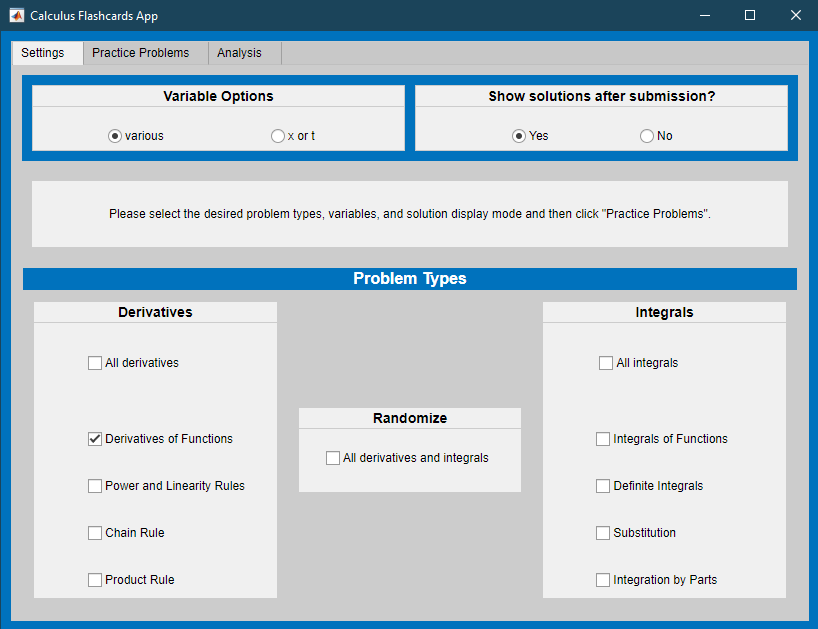](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

function [posRegs,negRegs,allOrderedRegs] = findSignSwitchIndexes(fVals,dVals,f0)
% fVals is a vector of doubles to be compared to a constant f0 at
% points given by dVals, a same-sized vector of doubles.
% Each nonnegative/nonpositive region is a row in posRegs/negRegs, respectively
% The first and last columns are flags (1/0) indicating (yes/no) need for
% interpolation at the beginning/end of the region
% The second column is the index into fVals/dVals of the first pair in that region
% The third column is the index into fVals/dVals of the last pair in that region
% If there are no fVals/dVals pairs in the region the second and third
% column will contain NaN
% allOrderedRegs combines posRegs and negRegs with a fifth column that
% tracks the sign (1 for positive, -1 for negative) in the order that they
% occur moving through dVals

ddVals = dVals(2:end)-dVals(1:end-1);

posDU = ddVals > 0;
zeroDU = ddVals == 0;
negDU = ones(size(ddVals))-posDU-zeroDU;

posF = fVals>=f0;
negF = fVals<=f0;

posPosVals = (posDU + posF(1:end-1) + posF(2:end))==3;
negNegVals = (negDU + negF(1:end-1) + negF(2:end))==3;
allPosVals = posPosVals + negNegVals;
startPosRegIdx = find((allPosVals - [0 allPosVals(1:end-1)])==1);
endPosRegIdx = find(([allPosVals(2:end) 0] - allPosVals)==-1);
if size(startPosRegIdx) ~= size(endPosRegIdx)
    ME = MException("IndexFinder:PairFailure","Unmatched start/end regions");
    throw(ME)
end
posRegs = zeros([length(startPosRegIdx),4]);
posRegs(:,2) = startPosRegIdx';
posRegs(:,3) = endPosRegIdx';

posNegVals = (posDU + negF(1:end-1) + negF(2:end))==3;
negPosVals = (negDU + posF(1:end-1) + posF(2:end))==3;
allNegVals = posNegVals + negPosVals;
startNegRegIdx = find((allNegVals - [0 allNegVals(1:end-1)])==1);
endNegRegIdx = find(([allNegVals(2:end) 0] - allNegVals)==-1);
if size(startNegRegIdx) ~= size(endNegRegIdx)
    ME = MException("IndexFinder:PairFailure","Unmatched start/end regions");
    throw(ME)
end
negRegs = zeros([length(startNegRegIdx),4]);
negRegs(:,2) = startNegRegIdx';
negRegs(:,3) = endNegRegIdx';

allZeroVals = zeroDU;

regIdentified = allPosVals + allNegVals + allZeroVals;

interpIdx = find(regIdentified == 0);
for k = 1:length(interpIdx)
    if ismember(interpIdx(k)+1,startPosRegIdx)
        idx = startPosRegIdx==(interpIdx(k)+1);
        posRegs(idx,1) = 1;
    elseif ismember(interpIdx(k)+1,startNegRegIdx)
        idx = startNegRegIdx==(interpIdx(k)+1);
        negRegs(idx,1) = 1;
    elseif (posDU(interpIdx(k)) && posF(interpIdx(k)+1))||(negDU(interpIdx(k)) && negF(interpIdx(k)+1))
        posRegs = [posRegs;1 nan nan 1]; %#ok<AGROW>
    elseif (negDU(interpIdx(k)) && posF(interpIdx(k)+1))||(posDU(interpIdx(k)) && negF(interpIdx(k)+1))
        negRegs = [negRegs;1 nan nan 1]; %#ok<AGROW>
    else
        warning("Unmatched index value tagged for interpolation.")
    end
    if ismember((interpIdx(k)-1),endPosRegIdx)
        idx = endPosRegIdx==(interpIdx(k)-1);
        posRegs(idx,4) = 1;
    elseif ismember((interpIdx(k)-1),endNegRegIdx)
        idx = endNegRegIdx==(interpIdx(k)-1);
        negRegs(idx,4) = 1;
    end
end

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);

allRegs = [posRegs ones([numPosRegs 1]);...
    negRegs -1*ones([numNegRegs 1])];
allOrderedRegs = sortrows(allRegs,2);
end


function xz = findInterpVal(xl,xr,fl,fr,f0)
% findInterpVals takes coordinates of two points (xl,fl) and (xr,fr) and an
% intermediate value f0 between fl and fr and returns the coordinate xz
% estimating where the line between them crosses the value y = f0
if (fr-f0)*(fl-f0)>=0
    ME = MException("InterpVal:IntervalError","f0 ("+f0+") is not between fl ("+fl+") and fr ("+fr+")");
    throw(ME)
end
%% Calculate the slope between (xl,fl) and (xr,fr)
mf = (fr-fl)/(xr-xl);
%% Solving the linear approximation f0 = mf*(xz-xl)+fl for xz
xz = (f0-fl)/mf+xl;

end

function varargout = showPosNegArea(ax,fVals,dVals,f0,overlapsFlag,pnFlag)
%plot(ax,dVals,fVals,"k")
hold on
[posRegs,negRegs,allRegs] = findSignSwitchIndexes(fVals,dVals,f0);
cols = ["b" "r"];

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);
[numRegs,~] = size(allRegs);

if overlapsFlag == 1
    alphaVal = 1/ceil(numRegs/2);
elseif overlapsFlag == 2
    alphaVal = .5;
else
    alphaVal = 1;
end

if pnFlag
    posGrp = drawColoredPolys(ax,fVals,dVals,posRegs,numPosRegs,cols(1),f0,alphaVal);
    negGrp = drawColoredPolys(ax,fVals,dVals,negRegs,numNegRegs,cols(2),f0,alphaVal);
    varargout{1} = posGrp;
    varargout{2} = negGrp;
else
    allGrp = drawColoredPolys(ax,fVals,dVals,allRegs,numRegs,cols(1),f0,alphaVal);
    varargout{1} = allGrp;
end

hold off
end

function polyGrp = drawColoredPolys(ax,fVals,dVals,Regs,numRegs,col,f0,alphaVal)
polyGrp = hggroup;
for k = 1:numRegs
    xVals = dVals(Regs(k,2):Regs(k,3)+1);
    yVals = fVals(Regs(k,2):Regs(k,3)+1);
    if Regs(k,1)
        xnew = findInterpVal(dVals(Regs(k,2)-1),xVals(1),...
            fVals(Regs(k,2)-1),yVals(1),f0);
        xVals = [xnew xVals]; %#ok<AGROW>
        yVals = [f0 yVals]; %#ok<AGROW>
    end
    if Regs(k,4)
        xnew = findInterpVal(xVals(end),dVals(Regs(k,3)+2),...
            yVals(end),fVals(Regs(k,3)+2),f0);
        xVals = [xVals xnew]; %#ok<AGROW>
        yVals = [yVals f0]; %#ok<AGROW>
    end
    x = [xVals flip(xVals)];
    y = [f0*ones(size(yVals)) flip(yVals)];
    patch(ax,x,y,col,"FaceAlpha",alphaVal,"Parent",polyGrp);
    pause(.1)
end
end

function lineGroup = addStartEnd(ax,x,lineGroup)
plot(ax,[x(end) x(end)],ax.YLim,"r-","LineWidth",2,"Parent",lineGroup);
plot(ax,[x(1) x(1)],ax.YLim,"c-","LineWidth",2,"Parent",lineGroup);
end

function lineGroup = animateStripes(ax,x,y,idx,lineGroup,flag)
% x and y are the same length, so this is just creating and adding to
% the relevant lineGroup collection of plotted lines at the index values
% given by idx
% if the flag is set, display as animation
if length(idx)>1
    p = plot(ax,[x(idx(1)) x(idx(1))],[0 y(idx(1))],"k","Parent",lineGroup);
    for k = 2:length(idx)
        copyobj(p,lineGroup)
        if x(idx(k))>= x(idx(k-1))
            lineGroup.Children(k).Color = "k";
            lineGroup.Children(k).LineWidth = 1;
        else
            lineGroup.Children(k).Color = "y";
            lineGroup.Children(k).LineWidth = 1;
        end
        lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
        lineGroup.Children(k).YData = [0 y(idx(k))];
        if flag
            drawnow
        end
    end
end
lineGroup = addStartEnd(ax,x,lineGroup);
end

function idx = defGStripes(gVals,dgVals) %#ok<DEFNU>
idx = zeros(size(dgVals));
idx(1) = 1;
for k = 1:length(idx)-1
    if dgVals(k) < 0
        try
            idx(k+1) = idx(k) + find(gVals(idx(k)+1:end) <= (gVals(idx(k)) + dgVals(k)),1);
        catch
            warning("Steps continue past the end of the defined domain.")
            idx(k+1) = length(gVals);
        end
    elseif dgVals(k) > 0
        try
            idx(k+1) = idx(k) + find(gVals(idx(k)+1:end) >= (gVals(idx(k)) + dgVals(k)),1);
        catch
            warning("Steps continue past the end of the defined domain.")
            idx(k+1) = length(gVals);
        end
    else
        idx(k+1)=idx(k);
    end
end
end

function setXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end

% % Practice Problem Generating Functions

function analyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

function [lastFive,errorCount] = check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = genProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
switch probType
    case 1 % Simple derivative
        syms f(x) g(x) x F(x) 
        [f(x),prevFuncType] = genFunDiff([1 3],x,[1 10],0);
        g(x) = genFunDiff([1 5],x,[5 10],prevFuncType);
        myFun = diff(f(g(varChoice)),varChoice);
        % Display the integral problem
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

function [myFunc,type] = genFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t+d);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t+d);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t+d);
    case 10
        f(t) = a*cos(b*t+d);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t+d);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t+d);
end
myFunc = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,probType,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    if length(totProbs)>1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        if length(totProbs) > 1
            [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
        else
            [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        end
    end
else
    if length(totProbs) > 1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        % check1 is defined in Helper Functions
        % check1 generates correct answers by differentiating myFun with respect to varChoice and compares
        % the result to myAnswer before updating the integer errorCount and matrix lastFive
    end
end
end

**Exercise 1 Solutions**

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

function check1a(gp,fsub,newMeasure,soln)
syms C x g f d 
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
meas = "dg";
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && newMeasure == "dx" && isequal(soln(x,C),x)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = newMeasure == meas;
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        disp("Correct.")
        displayFormula("dg/dx = gpans")
    else
        disp("You do not have the correct function for g'(x).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(g)")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"x")
        disp("The new measure should be in terms of g.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct.")
        displayFormula("int(f,x) = correctAns")
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$

function check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u f d
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
meas = "du";
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && newMeasure == "dt" && soln == 0
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = newMeasure == meas;
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        disp("Correct.")
        displayFormula("du/dt = gpans")
    else
        disp("You do not have the correct function for u'(t).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(u)")
    end
    if a5 && a6
        disp("You have the correct values for the bounds of the integral.")
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound.")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"t")
        disp("The new measure should be in terms of u.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct, the value of this integral is "+double(correctAns))
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Please try again.")
    end
end
end

c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

function check1c(gp,fsub,newMeasure,soln)
syms C x r q f d 
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
meas = "dq";
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && newMeasure == "dr" && isequal(soln(r,C),r)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = newMeasure == meas;
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        disp("Correct.")
        displayFormula("dq/dr = gpans")
    else
        disp("You do not have the correct function for q'(r).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(q)")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"r")
        disp("The new measure should be in terms of q.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct.")
        displayFormula("int(f,r) = correctAns")
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

function check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g f u dg du
% First substitution
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
comb1 = fg(g)*dg;
gaVal = ut(-1);
gbVal = ut(2);
% Second substitution
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
comb2 = fu(u)*du;
meas = "dg";
meas2 = "du";
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub(g),g) && ua == -1 && ub == 2 && newMeas1 == "dw" && soln == 0 ...
        && newMeas2 == "dw" && ua2 == -1 && ub2 == 2 && isequal(fusub(u),u)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = newMeas1 == meas;
    a2o3 = isAlways(fgsub(g)*str2sym(newMeas1)==comb1,"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = newMeas2 == meas2;
    a8 = isequal(fu(t),fusub(t));
    a7o8 = isAlways(fusub(u)*str2sym(newMeas2)==comb2,"Unknown","false");
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        disp("Correct.")
        displayFormula("dg/dw = gpans")
    else
        disp("You do not have the correct function for g'(w).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    elseif a2o3
        disp("Yes, the first integrand is ")
        displayFormula("f = fg*dg")
    else
        disp("You do not have the correct function for f(g)")
    end
    if a5 && a6
        disp("You have the correct values for the bounds of the first integral.")
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the first integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the first integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the first integral.")
    end
    if a3
        disp("Correct. The new measure for the first integral is "+ meas)
    elseif contains(newMeas1,"w")
        disp("The new measure should be in terms of g.")
    elseif a2o3
        disp("You have a correct integrand and measure for the first integral," + ...
            " but there is more than one way to break it down. What if the measure is simply dg?")
    else
        disp("Incorrect measure.")
    end
    if a9 && a10
        disp("You have the correct values for the bounds of the second integral.")
    elseif ~a9 && ~a10
        disp("You have not calcuated the correct values for the bounds of the second integral.")
    elseif a9
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the second integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the second integral.")
    end
    if a7 && a8
        disp("Correct. The new measure for the second integral is "+ meas + " and the integrand is")
        displayFormula("f = fu")
    elseif a7o8
        disp("Correct, but there is more than one way to break it down. What if the measure in the second integral is simply du?")
    elseif contains(newMeas2,"g") || contains(newMeas2,"w")
        disp("The new measure should be in terms of u.")
    elseif a7 && ~a8
        disp("Correct measure, but incorrect integrand in the second integral.")
    elseif ~a7 && a8
        disp("Incorrect measure, but correct integrand in the second integral.")
    else
        disp("Incorrect measure and incorrect integrand in the second integral.")
    end 
    if a4
        disp("Correct, the value of this integral is ")
        displayFormula("int(f,u)==correctAns(w,C)")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~((a2&a3)|a2o3) ~a4 ~a5 ~a6 ~((a7&a8)|a7o8)])
        disp("Please try again.")
    end
end
end